% (a)

Monte = 10e6;
Rounds = 0;

for i=1:Monte
    [p , r, ties] = chessduel(0.36,0.4,0.29,0.5,14);
    Rounds = Rounds+r;
end

average_rounds = Rounds/Monte

average_rounds = 12.8160

Monte = 10e6;
Rounds = 0;

for i=1:Monte
    [p , r , ties] = chessduel(0.36,0.4,0.29,0.5,14);
    if ties > 0
        Rounds = Rounds+1;
    end
end

probability_tie_break = Rounds/Monte

probability_tie_break = 0.1152

Monte = 10e6;
Rounds = 0;

for i=1:Monte
    [p , r , ties] = chessduel(0.36,0.4,0.29,0.5,14);
    if p(1) < p(2)
        Rounds = Rounds+1;
    end
end

probbility_B_winning = Rounds/Monte

probbility_B_winning = 0.2714

% (b)

Monte = 10e5;
Rounds = 0;
probbility_B_winning = [];

for p1 = 0.01:0.01:0.5
    p2 = 0.98*p1;
   for i=1:Monte
      [p , r , ties] = chessduel(p1,0.26,p2,0.29,14);
        if p(1) < p(2)
            Rounds = Rounds+1;
        end
   end

  probbility_B_winning = [probbility_B_winning Rounds/Monte];
  Rounds = 0;
end

probbility_B_winning; 

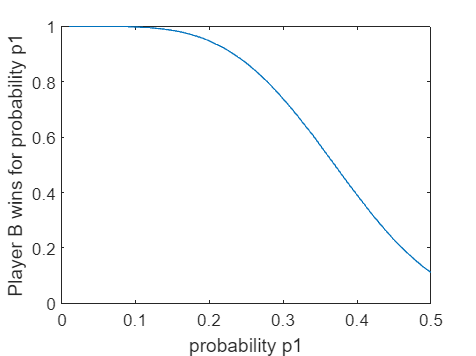

% plot

plot(0.01:0.01:0.5,probbility_B_winning)
xlabel('probability p1')
ylabel('Player B wins for probability p1')